clc;
clear;
close all;

%% Parameters
N_fft = 8;                    % Number of subcarriers (FFT size)
cp_len = 2;                   % Cyclic Prefix length
modOrder = 2;                 % BPSK (2 symbols)
bitsPerSymbol = log2(modOrder);
numBits = 4;                  % 4 bits to transmit (for 4 BPSK symbols)
numSymbols = numBits / bitsPerSymbol; % Number of symbols to transmit

fs = 20e6;                     % Sampling frequency (1 MHz)

% Subcarrier spacing (Hz) calculated from fs and N_fft
subcarrier_spacing = fs / N_fft;  
disp(['Subcarrier Spacing: ', num2str(subcarrier_spacing), ' Hz']);

Subcarrier Spacing: 2500000 Hz



%% 1. Generate Random Bits
bits = randi([0 1], numBits, 1);  % Random bits (4 bits)
disp('Random Bits:');

Random Bits:


disp(bits);

     0
     0
     0
     1




%% 2. Map Bits to Symbols (BPSK)
symbols = 2*bits - 1;  % BPSK: 0 → -1, 1 → +1
disp('Mapped BPSK Symbols:');

Mapped BPSK Symbols:


disp(symbols);

    -1
    -1
    -1
     1




%% 3. Frequency Domain (Before IFFT)
% Reshape the symbols into a 1xN_fft matrix (one symbol per subcarrier)
ofdm_symbols = zeros(N_fft, 1); 

% Assign the BPSK symbols to the frequency bins
% We skip the DC component (index 4) and assign symbols to other subcarriers
ofdm_symbols(4) = symbols(1);  % Subcarrier at -1
ofdm_symbols(6) = symbols(2);  % Subcarrier at +1
ofdm_symbols(3) = symbols(3);  % Subcarrier at -2
ofdm_symbols(7) = symbols(4);  % Subcarrier at +2

% Plot Frequency Domain before IFFT (Real part only for BPSK)
ofdm_symbols

ofdm_symbols =      0
     0
    -1
    -1
     0
    -1
     1
     0


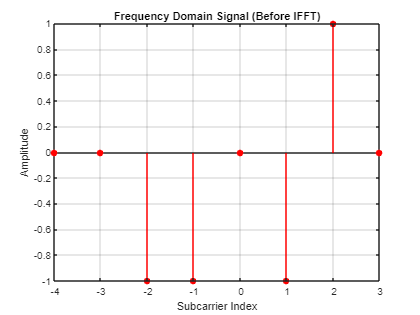

figure;
stem(-N_fft/2:N_fft/2-1, real(ofdm_symbols), 'r', 'filled');
title('Frequency Domain Signal (Before IFFT)');
xlabel('Subcarrier Index');
ylabel('Amplitude');
grid on;


%% 4. Apply IFFT (Frequency Domain to Time Domain)
% Perform IFFT on the frequency-domain symbols
ofdm_symbols_time = ifft(ofdm_symbols, N_fft);  % Time-domain signal without cyclic prefix

disp('OFDM Symbols (Time Domain):');

OFDM Symbols (Time Domain):


disp(ofdm_symbols_time.');

  -0.2500 + 0.0000i   0.1768 - 0.2500i   0.0000 + 0.0000i  -0.1768 + 0.2500i   0.2500 + 0.0000i  -0.1768 - 0.2500i   0.0000 + 0.0000i   0.1768 + 0.2500i




%% 5. Add Cyclic Prefix
% Take the last cp_len samples from the time-domain signal and add them to the beginning
ofdm_symbols_cp = [ofdm_symbols_time(end-cp_len+1:end); ofdm_symbols_time]; 

disp('OFDM Symbols with Cyclic Prefix:');

OFDM Symbols with Cyclic Prefix:


disp(ofdm_symbols_cp.');

   0.0000 + 0.0000i   0.1768 + 0.2500i  -0.2500 + 0.0000i   0.1768 - 0.2500i   0.0000 + 0.0000i  -0.1768 + 0.2500i   0.2500 + 0.0000i  -0.1768 - 0.2500i   0.0000 + 0.0000i   0.1768 + 0.2500i



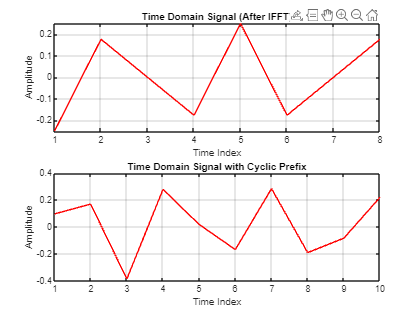


%% 5.5 Add AWGN Noise
noise_variance = 0.01;  % Given noise variance
noise = sqrt(noise_variance/2) * (randn(size(ofdm_symbols_cp)) + 1j*randn(size(ofdm_symbols_cp)));  % Complex AWGN

ofdm_symbols_cp = ofdm_symbols_cp + noise;

%% 6. Plot Time Domain Signals
figure;

subplot(2,1,1);
plot(real(ofdm_symbols_time), 'r');
title('Time Domain Signal (After IFFT)');
xlabel('Time Index');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(real(ofdm_symbols_cp), 'r');
title('Time Domain Signal with Cyclic Prefix');
xlabel('Time Index');
ylabel('Amplitude');
grid on;

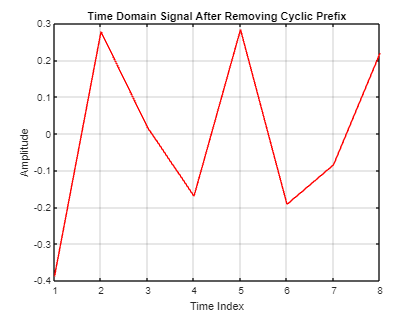




%% 7. Frequency Domain After Removing Cyclic Prefix
% Remove the cyclic prefix (take the samples after the cyclic prefix)
ofdm_symbols_no_cp = ofdm_symbols_cp(cp_len+1:end);

%% 8. Plot Time Domain After Removing Cyclic Prefix
figure;
plot(real(ofdm_symbols_no_cp), 'r');
title('Time Domain Signal After Removing Cyclic Prefix');
xlabel('Time Index');
ylabel('Amplitude');
grid on;

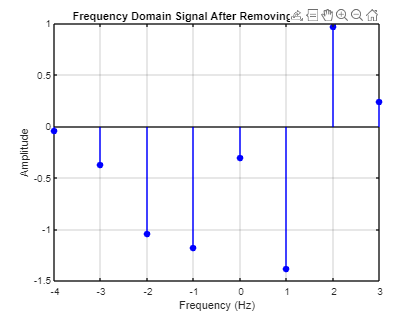


% Plot the frequency domain after removing the cyclic prefix
figure;
signal_freq_no_cp = (fft(ofdm_symbols_no_cp, N_fft));  % Apply FFT and shift the zero frequency component to the center
frequencies = (-N_fft/2):(N_fft/2)-1;  % Frequency bins

% Plot real part of the signal in frequency domain after removing cyclic prefix
stem(frequencies, real(signal_freq_no_cp), 'b', 'filled');
title('Frequency Domain Signal After Removing Cyclic Prefix');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;